## FITZHUGH_NAGUMO

- **SECCIÓN 3.2**

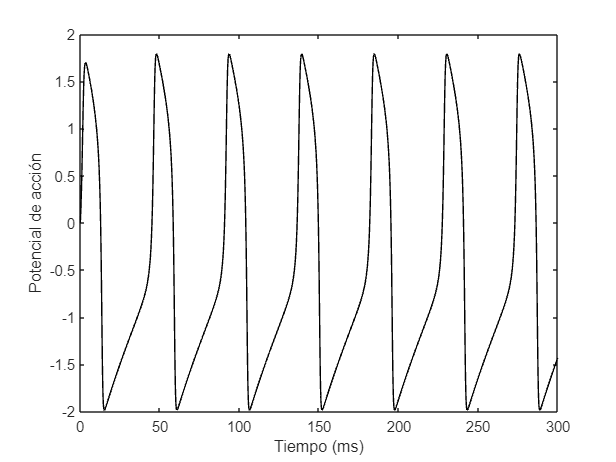

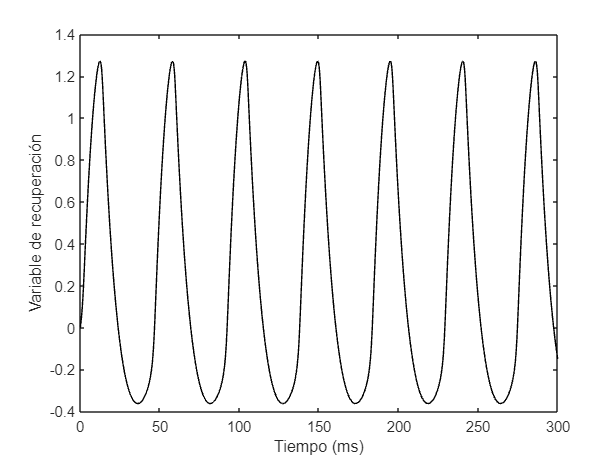

ta = 10000; n = 100000; a = 0.7; b = 0.8; I = 0.35; phi = 0.08; y0 = [0; 0];
 
f = @(y) [y(1) - y(1)^3/3 - y(2) + I;
          phi * (y(1) + a - b * y(2))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación'};
  
for i = 1:2
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,300])
end

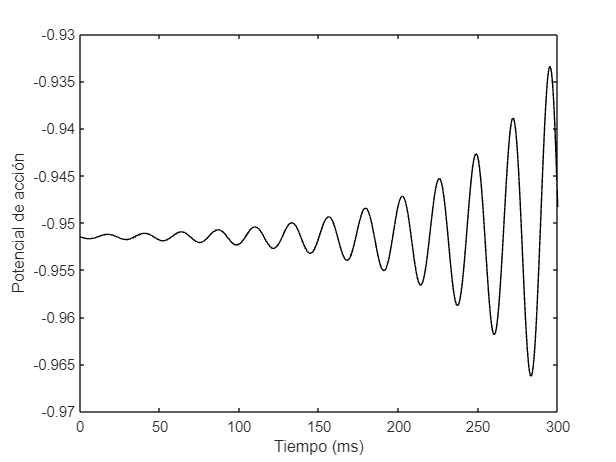

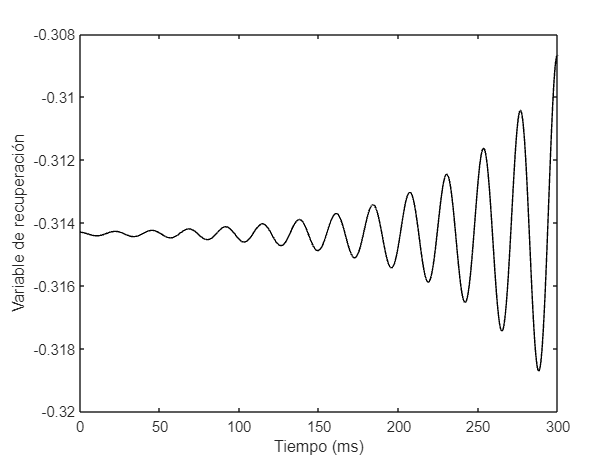

ta = 10000; n = 100000; a = 0.7; b = 0.8; I = 0.35; phi = 0.08; y0 = [-0.9515; -0.3143];
 
f = @(y) [y(1) - y(1)^3/3 - y(2) + I;
          phi * (y(1) + a - b * y(2))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación'};
  
for i = 1:2
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,300])
end

- **1 PUNTO DE EQUILIBRIO**

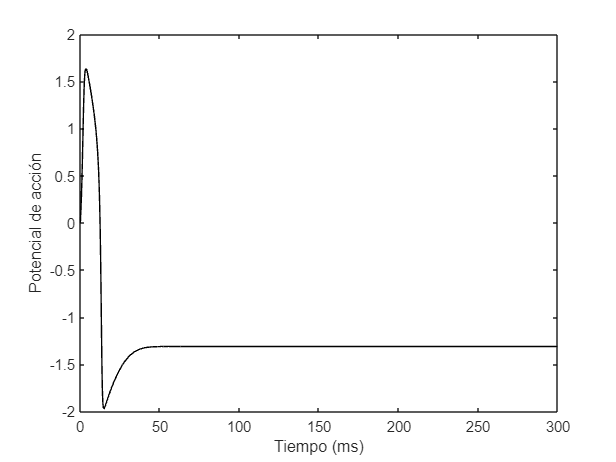

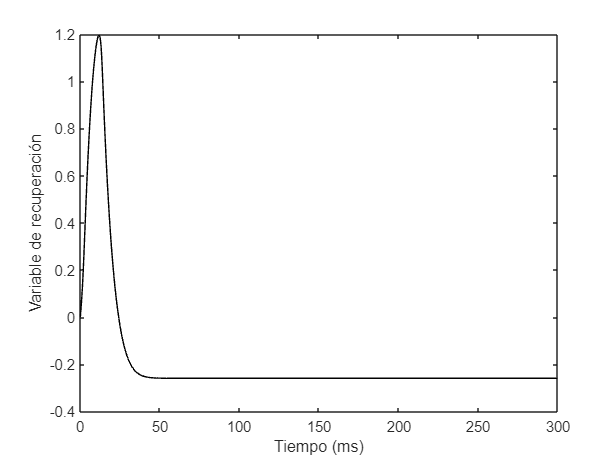

ta = 10000; n = 100000; a = 1; b = 1.2; I = 0.3; phi = 0.08; y0 = [0; 0];
 
f = @(y) [y(1) - y(1)^3/3 - y(2) + I;
          phi * (y(1) + a - b * y(2))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación'};
  
for i = 1:2
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,300])
end

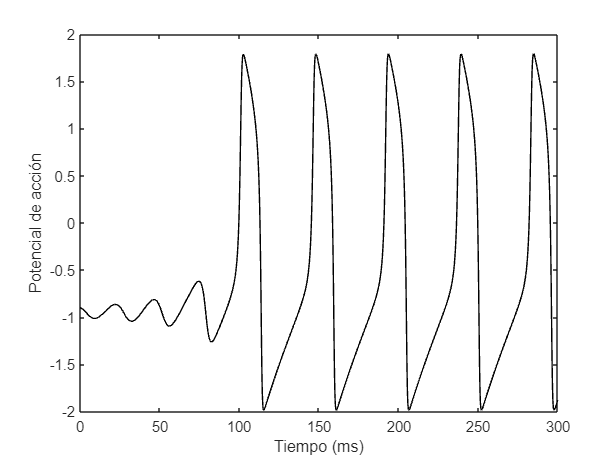

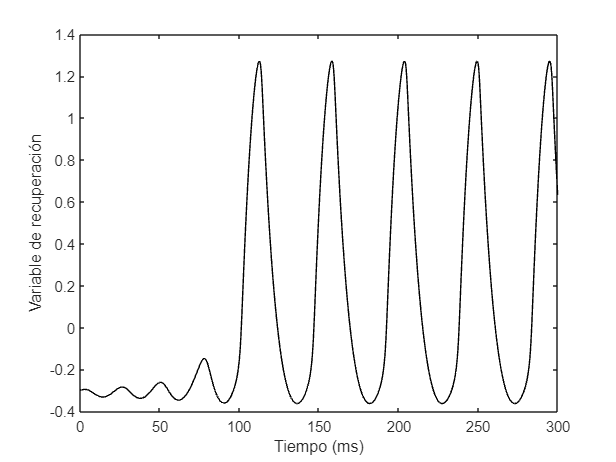

ta = 10000; n = 100000; a = 0.7; b = 0.8; I = 0.35; phi = 0.08; y0 = [-0.9; -0.3];
 
f = @(y) [y(1) - y(1)^3/3 - y(2) + I;
          phi * (y(1) + a - b * y(2))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación'};
  
for i = 1:2
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,300])
end

- **2 PUNTOS DE EQUILIBRIO**

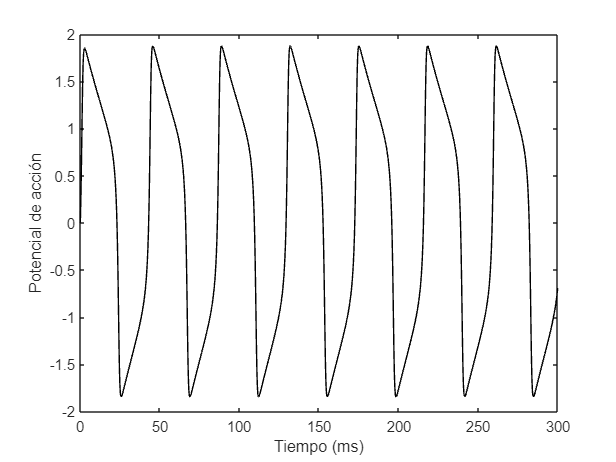

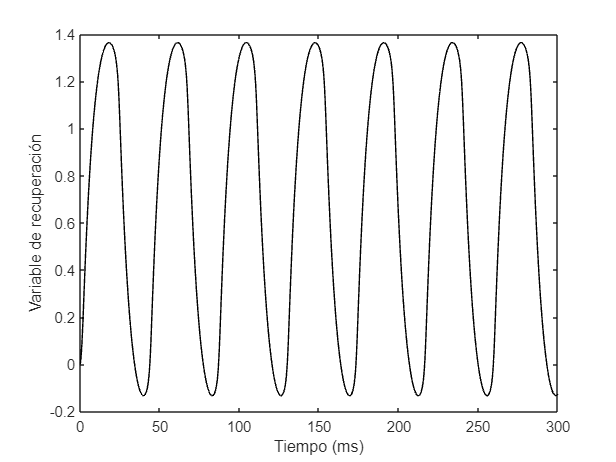

ta = 10000; n = 100000; a = 0.7; b = 1.2; I = 1170/1861; phi = 0.08; y0 = [0; 0];
 
f = @(y) [y(1) - y(1)^3/3 - y(2) + I;
          phi * (y(1) + a - b * y(2))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación'};
  
for i = 1:2
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,300])
end

- **3 PUNTOS DE EQUILIBRIO**

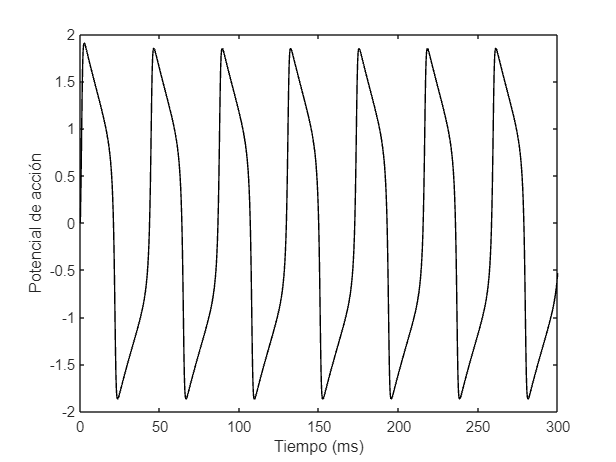

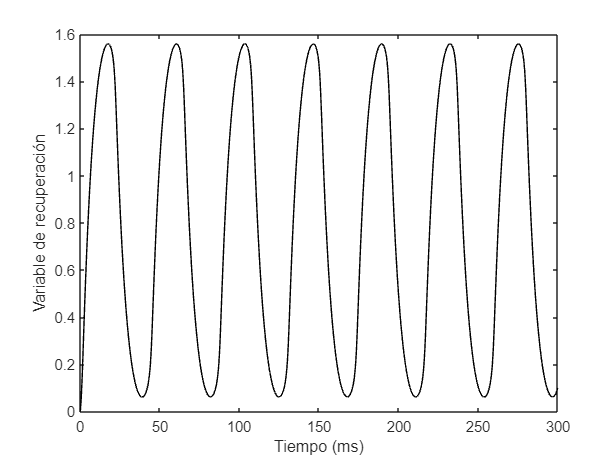

ta = 10000; n = 100000; a = 1; b = 1.2; I = 0.8; phi = 0.08; y0 = [0; 0];
 
f = @(y) [y(1) - y(1)^3/3 - y(2) + I;
          phi * (y(1) + a - b * y(2))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación'};
  
for i = 1:2
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,300])
end

## HINDMARSH-ROSE

- **SECCIÓN 3.3**

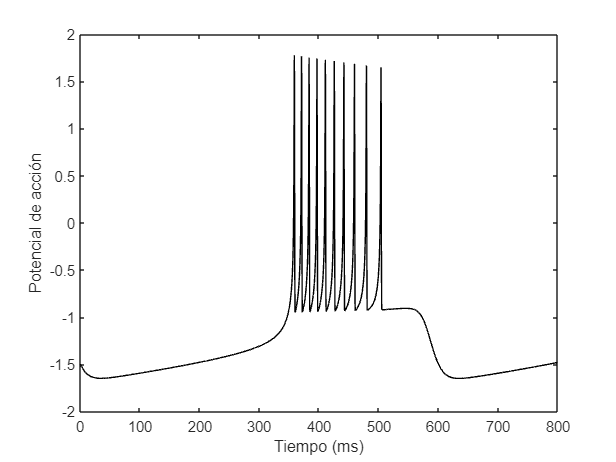

ta = 1000; n = 100000; a = 1; b = 3; c = 1; d = 5; r = 0.001; s = 3; Vr = -8/5; I = 1.4; y0 = [-1.5; -10; 1.5];
 
f = @(y) [y(2) - a*y(1)^3 + b*y(1)^2 + I - y(3);
    c - d*y(1)^2 - y(2);
    r * (s * (y(1) - Vr) - y(3))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación', 'Corriente de adaptación'};
  
for i = 1
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,800])
end

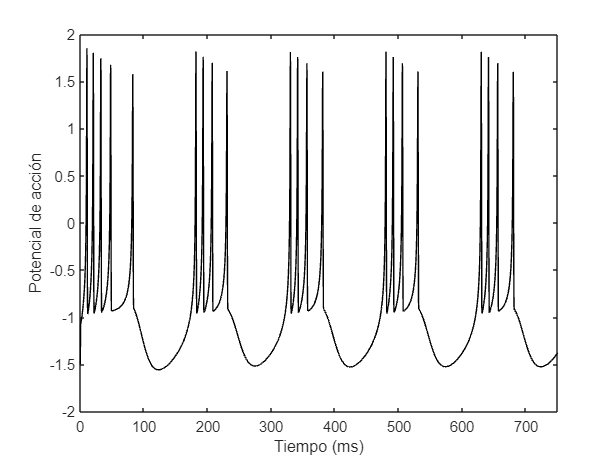

ta = 1000; n = 100000; a = 1; b = 3; c = 1; d = 5; r = 0.005; s = 4; Vr = -8/5; I = 2.5; y0 = [-1.5; -5; 2];
 
f = @(y) [y(2) - a*y(1)^3 + b*y(1)^2 + I - y(3);
    c - d*y(1)^2 - y(2);
    r * (s * (y(1) - Vr) - y(3))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación', 'Corriente de adaptación'};
  
for i = 1
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,750])
end

- **1 PUNTO DE EQUILIBRIO**

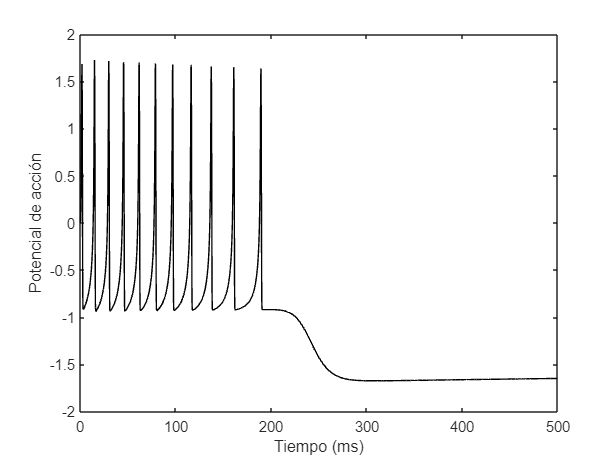

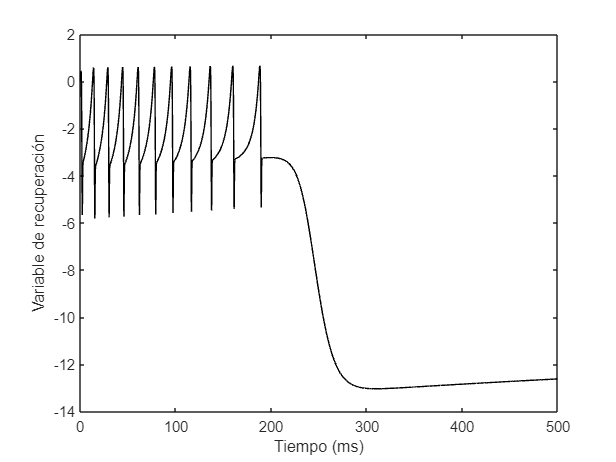

ta = 10000; n = 100000; a = 1; b = 3; c = 1; d = 5; r = 0.001; s = 1; Vr = -8/5; I = 0.1; y0 = [0; 0; 0];
 
f = @(y) [y(2) - a*y(1)^3 + b*y(1)^2 + I - y(3);
    c - d*y(1)^2 - y(2);
    r * (s * (y(1) - Vr) - y(3))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación', 'Corriente de adaptación'};
  
for i = 1:2
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,500])
end

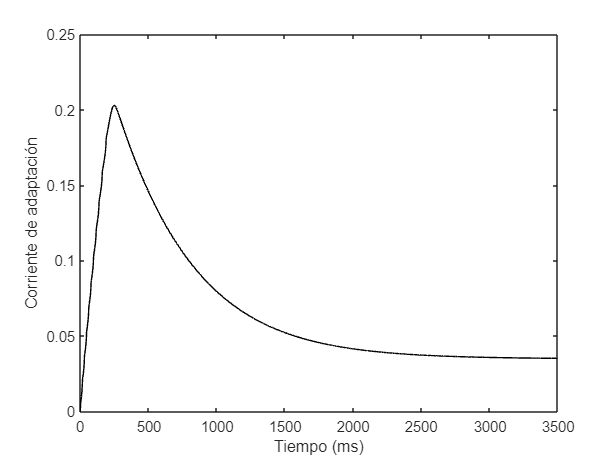

plot(t, y(3,:), 'k')
xlabel('Tiempo (ms)')
ylabel(ejesY{3})
xlim([0,3500])

- **2 PUNTOS DE EQUILIBRIO**

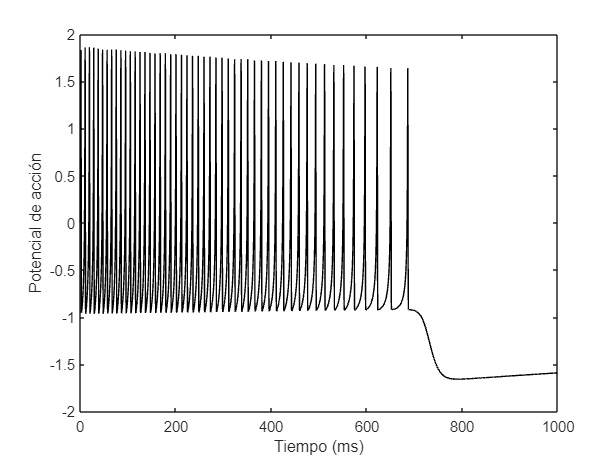

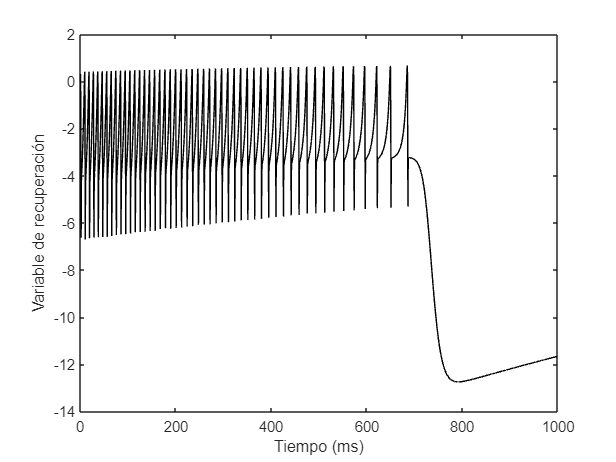

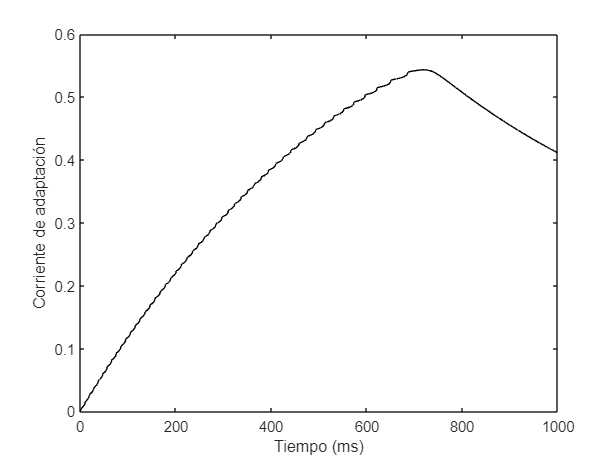

ta = 10000; n = 100000; a = 1; b = 3; c = 1; d = 5; r = 0.001; s = 1; Vr = -8/5; I = 61/135; y0 = [0; 0; 0];
 
f = @(y) [y(2) - a*y(1)^3 + b*y(1)^2 + I - y(3);
    c - d*y(1)^2 - y(2);
    r * (s * (y(1) - Vr) - y(3))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación', 'Corriente de adaptación'};
  
for i = 1:3
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,1000])
end

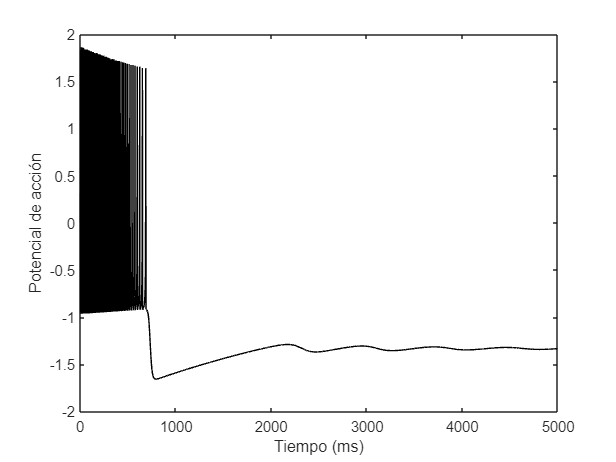

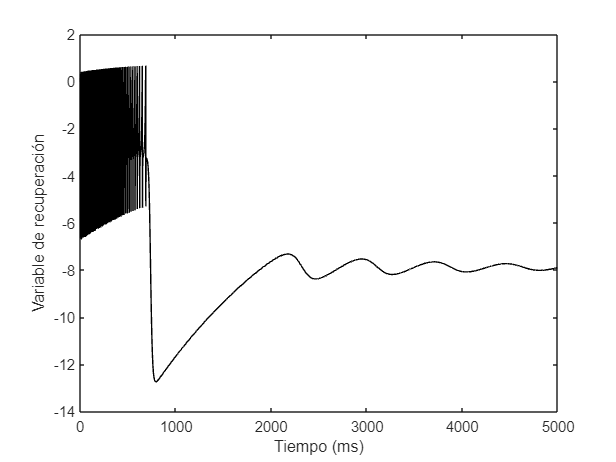

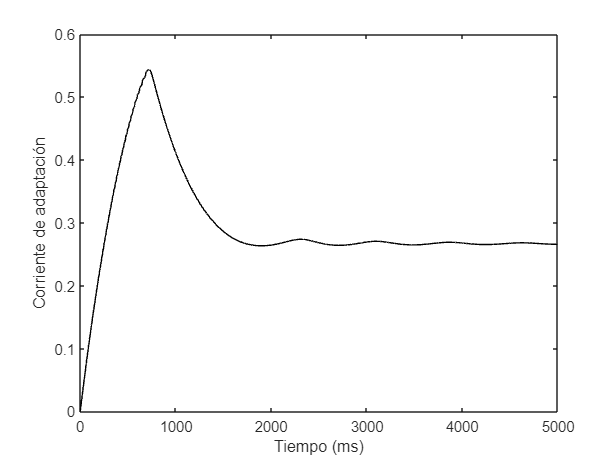

ta = 10000; n = 100000; a = 1; b = 3; c = 1; d = 5; r = 0.001; s = 1; Vr = -8/5; I = 61/135; y0 = [0; 0; 0];
 
f = @(y) [y(2) - a*y(1)^3 + b*y(1)^2 + I - y(3);
    c - d*y(1)^2 - y(2);
    r * (s * (y(1) - Vr) - y(3))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación', 'Corriente de adaptación'};
  
for i = 1:3
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,5000])
end

- **3 PUNTOS DE EQUILIBRIO**

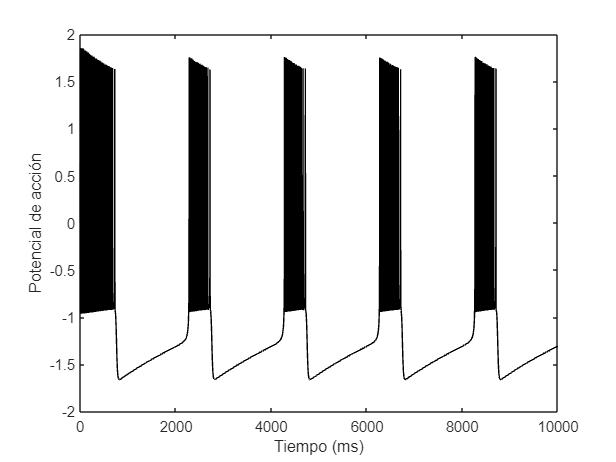

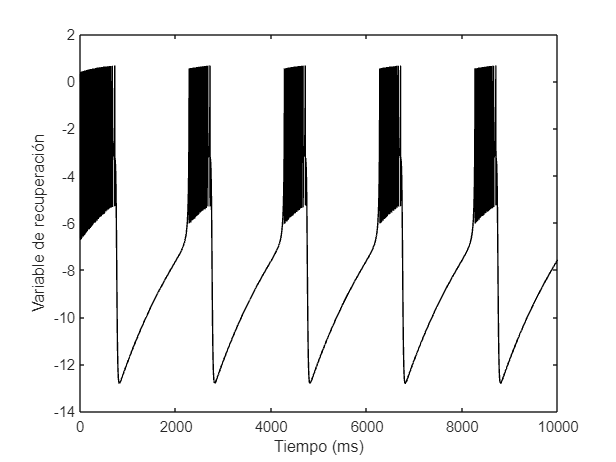

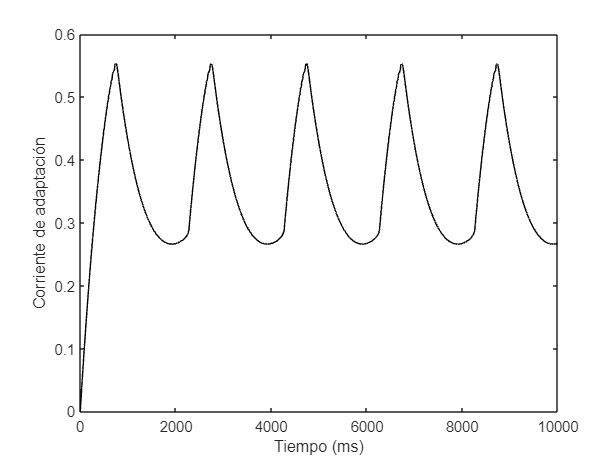

ta = 10000; n = 100000; a = 1; b = 3; c = 1; d = 5; r = 0.001; s = 1; Vr = -8/5; I = 0.455; y0 = [0; 0; 0];
 
f = @(y) [y(2) - a*y(1)^3 + b*y(1)^2 + I - y(3);
    c - d*y(1)^2 - y(2);
    r * (s * (y(1) - Vr) - y(3))];

[t, y] = rk4(f, ta, y0, n);

ejesY = {'Potencial de acción', 'Variable de recuperación', 'Corriente de adaptación'};
  
for i = 1:3
    figure
    plot(t, y(i,:), 'k')
    xlabel('Tiempo (ms)')
    ylabel(ejesY{i})
    xlim([0,10000])
end

function [t, y] = rk4(f, ta, y0, n)

    h = ta / n;             
    t = linspace(0, ta, n + 1);     
    y = zeros(length(y0), n + 1);      
    y(:, 1) = y0;       
    
    for i = 1:n
      k1 = f(y(:, i));  
      k2 = f(y(:, i) + (h / 2) * k1);
      k3 = f(y(:, i) + (h / 2) * k2);
      k4 = f(y(:, i) + h * k3);
      y(:, i + 1) = y(:, i) + (h / 6) * (k1 + 2 * k2 + 2 * k3 + k4);
    end   
end